# Camille Rakotoranto, April 2025, MATLAB R2024b, The MathWorks Inc., Natick, MA, USA

# Statistical Analysis following FOOOF Algorithm

This script allows for statistical analyses of the data following the application of FOOOF using  FOOOFImplementation.mlx. The stattistical analyses address the specific aims of the thesis:

- **Aim 1: Validation of FOOOF for ear-EEG**

                    Preliminary Analysis: Inter-gender comparison of pre-FOOOF peak alpha power

                    Analysis 1: Intra-configuration of pre- and post-FOOOF periodic parameters

- **Aim 2: An evaluation of the differences between scalp- and ear-EEG, allowing an identification of the scalp configuration most strongly correlated with ear-EEG.**

                    Analysis 2: Inter-configuration comparison of periodic and aperiodic parameters and computation of respective correlations

- **Aim 3: An evaluation of the quality metrics of ear-EEG using FOOOF.**

                    Analysis 3: Comparison of hemispheric scalp configurations T7-Oz and T8-Oz (periodic and aperiodic parameters). This is used to establish a unified gold standard for Analysis 4.

                    Analysis 4: Comparison of inter-hemspheric configurations' quality metrics with respect to the gold standard established in Analysis 3

**To avoid errors, the script requires sequential execution from Section 1 to 8.**

- Section 1: Loading in Data

- Section 2: Inter-gender analysis 

- Section 3: Implementation of Analysis 1

- Section 4: Implementation of Analysis 2

- Section 5: Continuation of Implementation of Analysis 2

- Section 6: Implementation of Analysis 3 

- Section 7: Continuation of Analysis 3

- Section 8: Implementation of Analysis 4

Note: Due to the absence of a robust outlier ROUT test implementation in MATLAB, analysis in MATLAB was performed without outlier exclusion. Results were confirmed and, if required, corrected using Prism 10 – where outliers were identified prior to subsequent tests. 

## Section 1: Loading in Data

%% Load Data
load('fooof_results.mat');
load('fooof_average_results.mat');


%% Define conditions and Sites
conditions = {'rs', 'ec', 'eo'};
configurations = {'T7', 'T8', 'T7T8', 'ear'};


## Section 2: Inter-gender analysis 

This section provides an inter-gender comparison for pre-FOOOF peak alpha power and the aperiodic exponent for all configurations and conditions. It requires the defintion of the indices corresponding to males and females.

num_subjects = 15;

% Rows corresponding to males and females
male_indices = [1, 3, 5, 6, 10]; % change with actual male indices
female_indices = [2, 4, 7, 8, 9, 11, 12, 13, 14, 15]; % change with actual female indices

% Initialize storage for male and female parameters
male_peak_alpha_power = struct();
female_peak_alpha_power = struct();
male_aperiodic_exponent = struct();
female_aperiodic_exponent = struct();

% Initialize storage struct
results = struct();

% Extract paramaters for the subjects
for cond = conditions
    cond = cond{1};

    for configuration = configurations
        configuration = configuration{1};

        % Initialise the structs
        male_peak_alpha_power.(cond).(configuration) = [];
        female_peak_alpha_power.(cond).(configuration) = [];
        male_aperiodic_exponent.(cond).(configuration) = [];
        female_aperiodic_exponent.(cond).(configuration) = [];
        
        for subject = 1:num_subjects
            % Collect the parameters need
            % Pre-FOOOF PSD
            psd_original = fooof_results(subject).(configuration).(cond).power_spectrum;
            freqs = fooof_results(subject).(configuration).(cond).freqs;
            % Aperiodic parameters
            aperiodic_params = fooof_results(subject).(configuration).(cond).aperiodic_params;
            
            % Extract the peak alpha powers 
            alpha_idx = find(freqs >= 8 & freqs <= 12);
            [max_psd, ~] = max(psd_original(alpha_idx));
            
            % Extract the aperiodic exponent
            % If the FOOOF model used a 'knee' then it has 3 columns
            if size(aperiodic_params, 2) == 3
                aperiodic_exponent = aperiodic_params(:, 3); 
            else
                % otherwise there are 2 columns
                aperiodic_exponent = aperiodic_params(:, 2); 
            end
            
            % Store peak alpha power and aperiodic exponent based on the
            % gender
            if ismember(subject, male_indices)
                male_peak_alpha_power.(cond).(configuration) = [male_peak_alpha_power.(cond).(configuration); max_psd];
                male_aperiodic_exponent.(cond).(configuration) = [male_aperiodic_exponent.(cond).(configuration); aperiodic_exponent];
            elseif ismember(subject, female_indices)
                female_peak_alpha_power.(cond).(configuration) = [female_peak_alpha_power.(cond).(configuration); max_psd];
                female_aperiodic_exponent.(cond).(configuration) = [female_aperiodic_exponent.(cond).(configuration); aperiodic_exponent];
            end
        end
        
        % Find the mean and standard deviation based on the gender
        results.(cond).(configuration).male_mean_peak = mean(male_peak_alpha_power.(cond).(configuration));
        results.(cond).(configuration).male_std_peak = std(male_peak_alpha_power.(cond).(configuration));
        results.(cond).(configuration).female_mean_peak = mean(female_peak_alpha_power.(cond).(configuration));
        results.(cond).(configuration).female_std_peak = std(female_peak_alpha_power.(cond).(configuration));
        
        results.(cond).(configuration).male_mean_exponent = mean(male_aperiodic_exponent.(cond).(configuration));
        results.(cond).(configuration).male_std_exponent = std(male_aperiodic_exponent.(cond).(configuration));
        results.(cond).(configuration).female_mean_exponent = mean(female_aperiodic_exponent.(cond).(configuration));
        results.(cond).(configuration).female_std_exponent = std(female_aperiodic_exponent.(cond).(configuration));
        
        %% Determine if there's a significant difference
        % Check normality of the groups
        if numel(male_peak_alpha_power.(cond).(configuration)) > 1 && numel(female_peak_alpha_power.(cond).(configuration)) > 1
            [h_male_peak, p_male_peak] = swtest(male_peak_alpha_power.(cond).(configuration));
            [h_female_peak, p_female_peak] = swtest(female_peak_alpha_power.(cond).(configuration));
            
            % If normal perform unpaired t-test
            if h_male_peak == 0 && h_female_peak == 0
                [h_peak, p_peak, ci_peak, stats_peak] = ttest2(male_peak_alpha_power.(cond).(configuration), female_peak_alpha_power.(cond).(configuration));
                test_type_peak = 'Unpaired t-test';
            else
                % otherwise use Mann-Whitney U-test (same as the Wilcoxon
                % rank-sum test)
                [p_peak, ~] = ranksum(male_peak_alpha_power.(cond).(configuration), female_peak_alpha_power.(cond).(configuration));
                test_type_peak = 'Mann-Whitney U-test';
            end
            
            % Store results
            results.(cond).(configuration).p_value_peak = p_peak;
            results.(cond).(configuration).test_type_peak = test_type_peak;
        end
        
        % Repeat for the aperiodic exponent
        if numel(male_aperiodic_exponent.(cond).(configuration)) > 1 && numel(female_aperiodic_exponent.(cond).(configuration)) > 1
            [h_male_exp, p_male_exp] = swtest(male_aperiodic_exponent.(cond).(configuration));
            [h_female_exp, p_female_exp] = swtest(female_aperiodic_exponent.(cond).(configuration));
            
            if h_male_exp == 0 && h_female_exp == 0
                [h_exp, p_exp, ci_exp, stats_exp] = ttest2(male_aperiodic_exponent.(cond).(configuration), female_aperiodic_exponent.(cond).(configuration));
                test_type_exp = 'Paired t-test';
            else
                [p_exp, ~] = ranksum(male_aperiodic_exponent.(cond).(configuration), female_aperiodic_exponent.(cond).(configuration));
                test_type_exp = 'Mann-Whitney U-test';
            end
            
            results.(cond).(configuration).p_value_exp = p_exp;
            results.(cond).(configuration).test_type_exp = test_type_exp;
        end
    end
end

% Show all results
for cond = conditions
    cond = cond{1};
    for configuration = configurations
        configuration = configuration{1};
        fprintf('Condition: %s, Site: %s\n', cond, configuration);
        fprintf('Male Peak Alpha Power: Mean = %.2f, Std = %.2f\n', results.(cond).(configuration).male_mean_peak, results.(cond).(configuration).male_std_peak);
        fprintf('Female Peak Alpha Power: Mean = %.2f, Std = %.2f\n', results.(cond).(configuration).female_mean_peak, results.(cond).(configuration).female_std_peak);
        fprintf('Statistical comparison for peak alpha power (p-value): %.4f (%s)\n', results.(cond).(configuration).p_value_peak, results.(cond).(configuration).test_type_peak);
        fprintf('Male Peak Alpha Power Values:\n');
        disp(male_peak_alpha_power.(cond).(configuration)');
        fprintf('Female Peak Alpha Power Values:\n');
        disp(female_peak_alpha_power.(cond).(configuration)');
        
        fprintf('Male Aperiodic Exponent: Mean = %.2f, Std = %.2f\n', results.(cond).(configuration).male_mean_exponent, results.(cond).(configuration).male_std_exponent);
        fprintf('Female Aperiodic Exponent: Mean = %.2f, Std = %.2f\n', results.(cond).(configuration).female_mean_exponent, results.(cond).(configuration).female_std_exponent);
        fprintf('Statistical comparison for aperiodic exponent (p-value): %.4f (%s)\n', results.(cond).(configuration).p_value_exp, results.(cond).(configuration).test_type_exp);
        fprintf('Male Aperiodic Exponent Values:\n');
        disp(male_aperiodic_exponent.(cond).(configuration)');
        fprintf('Female Aperiodic Exponent Values:\n');
        disp(female_aperiodic_exponent.(cond).(configuration)');
        fprintf('\n');
    end
end

## Section 3: Implementation of Analysis 1

This section provides an intra-configuration analysis of pre- and post-FOOOF periodic parameters

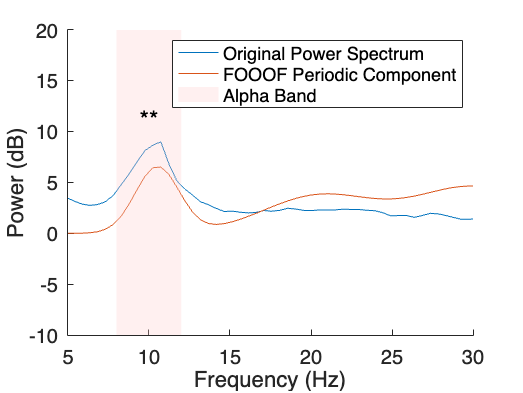

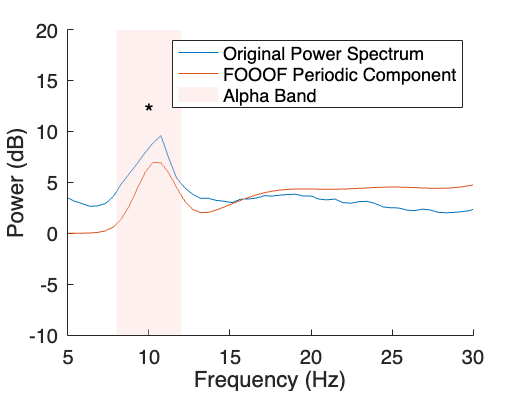

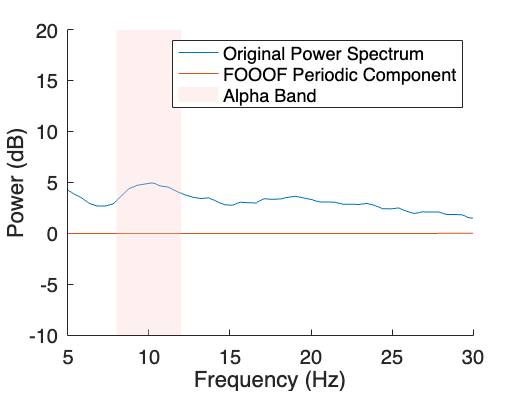

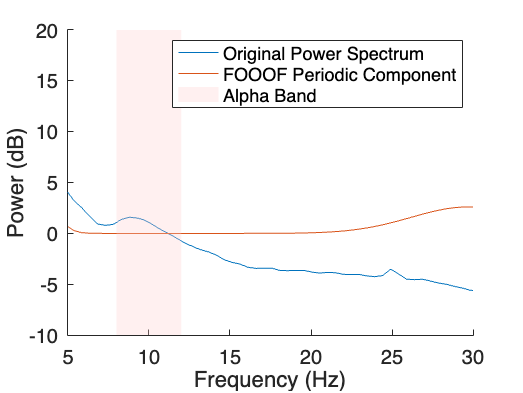

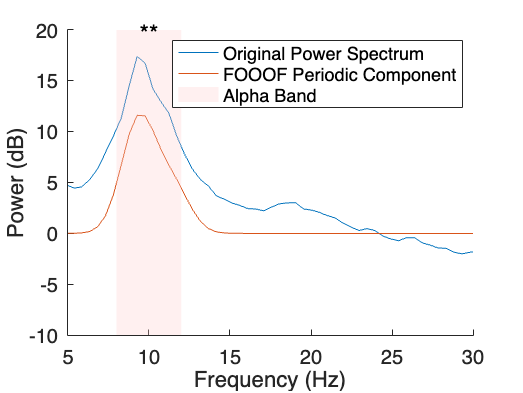

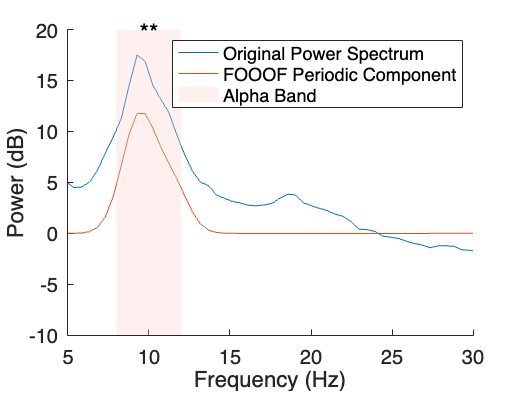

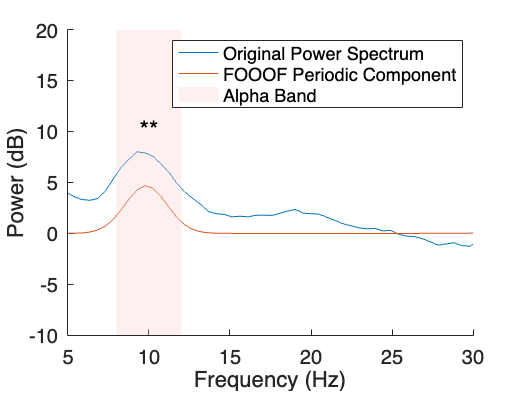

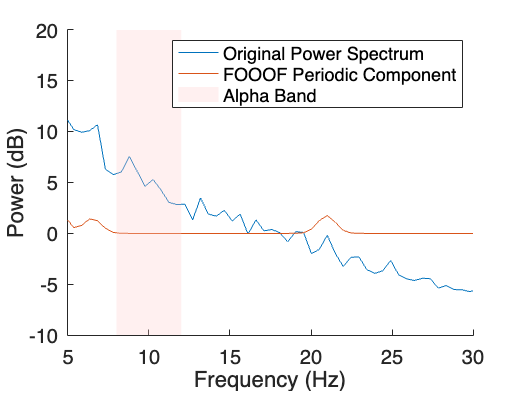

%% Initialize structs to store parameters
num_subjects = length(fooof_results);
group_power_spectrum_peak = struct();
group_fooof_spectrum_peak = struct();
p_values = struct();
means_and_stds = struct();

% Define the alpha band used for the analysis
alpha_band = [8, 12];


%%%%%%%%%%% Analysis for the Peak Alpha Power

% Initialize the table to present the results
results_table = [];

% Initialise the structs to store the relevant data for each condition and configuration
for cond = conditions
    cond = cond{1};
    for configuration = configurations
        configuration = configuration{1};
        
        % Initialize storage for the group data
        group_power_spectrum_peak.(cond).(configuration) = [];
        group_fooof_spectrum_peak.(cond).(configuration) = [];
        p_values.(cond).(configuration) = NaN;
        means_and_stds.(cond).(configuration) = struct('mean_psd', [], 'std_psd', [], 'mean_fooof', [], 'std_fooof', []);
    end
end

%% Collect the data for each subject for each condition and configuration
for subject = 1 : num_subjects
    for cond = conditions
        cond = cond{1};
        for configuration = configurations
            configuration = configuration{1};
            
            % Store the pre-FOOOF PSD
            psd_original = fooof_results(subject).(configuration).(cond).power_spectrum;
            % Store the FOOOF-reconstructed PSD
            psd_fooofed = fooof_results(subject).(configuration).(cond).fooofed_spectrum;
            % Store the frequencies
            freqs = fooof_results(subject).(configuration).(cond).freqs;
            % Store the FOOOF-adjusted periodic peaks
            periodic_params = fooof_results(subject).(configuration).(cond).gaussian_params; 
            % Store the aperiodic fit
            psd_aperiodic = fooof_results(subject).(configuration).(cond).ap_fit;
            
            %% Find the alpha band peak powers in the pre-FOOOF PSD
            alpha_idx = find(freqs >= 8 & freqs <= 12);
            [max_psd, ~] = max(psd_original(alpha_idx));
            group_power_spectrum_peak.(cond).(configuration) = [group_power_spectrum_peak.(cond).(configuration); max_psd];
            
            % Find the alpha band peak powers post-FOOOF
            alpha_peaks = periodic_params(periodic_params(:,1) >= 8 & periodic_params(:,1) <= 12, :);
            if ~isempty(alpha_peaks)
                [~, max_idx] = max(alpha_peaks(:,2));
                max_alpha_peak = alpha_peaks(max_idx, 2);
                group_fooof_spectrum_peak.(cond).(configuration) = [group_fooof_spectrum_peak.(cond).(configuration); max_alpha_peak];
            else
                % If there is no peak within the alpha band then take the maximum alpha power in the periodic fit
                alpha_idx_fooof = find(freqs >= 8 & freqs <= 12);
                psd_periodic = psd_fooofed - psd_aperiodic;
                max_fooof = max(psd_periodic(alpha_idx_fooof));
                group_fooof_spectrum_peak.(cond).(configuration) = [group_fooof_spectrum_peak.(cond).(configuration); max_fooof];
            end
        end
    end
end

%% Perform intra-configuration analysis for each condition and configuration
for cond = conditions
    cond = cond{1};
    for configuration = configurations
        configuration = configuration{1};
        
        x = group_power_spectrum_peak.(cond).(configuration);
        y = group_fooof_spectrum_peak.(cond).(configuration);

        % Check normality to perform either a paired t-test or Wilcoxon
        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;

            % Store the results in the table
            results_table = [results_table; {cond, configuration, p, numel(x), num2str(x'), num2str(y'), test_type, means_and_stds.(cond).(configuration).mean_psd, means_and_stds.(cond).(configuration).std_psd, means_and_stds.(cond).(configuration).mean_fooof, means_and_stds.(cond).(configuration).std_fooof}];
            
            %% Plot the pre-FOOOF PSD and FOOOF periodic component for a graphical representatio
            figure;
            hold on;
            
            % Extract the fits needed for the plot
            freqs = fooof_avg_results.(configuration).(cond).freqs;
            psd_original = fooof_avg_results.(configuration).(cond).power_spectrum;
            fooof_spectrum = fooof_avg_results.(configuration).(cond).fooofed_spectrum;
            aperiodic_fit = fooof_avg_results.(configuration).(cond).ap_fit;
            periodic_fit = fooof_spectrum - aperiodic_fit;
            
            plot(freqs, psd_original, 'DisplayName', 'Original Power Spectrum');
            plot(freqs, periodic_fit, 'DisplayName', 'FOOOF Periodic Component');
            
            % Emphaise the alpha band
            alpha_x = [alpha_band(1), alpha_band(2), alpha_band(2), alpha_band(1)]; 
            alpha_y = [-10, -10, 20, 20]; 
            fill(alpha_x, alpha_y, [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'DisplayName', 'Alpha Band'); 
            
            % Display the signicant difference in peak alpha power, if any.
            if p < 0.0001
                asterisks = '****';
            elseif p < 0.001
                asterisks = '***';
            elseif p < 0.01
                asterisks = '**';
            elseif p < 0.05
                asterisks = '*';
            else
                asterisks = '';
            end
            
            % Position the astericks above the maximum
            if ~isempty(asterisks)
                alpha_idx = freqs >= alpha_band(1) & freqs <= alpha_band(2);
                max_power_in_alpha = max([max(psd_original(alpha_idx)), max(periodic_fit(alpha_idx))]);
                text(mean(alpha_band), max_power_in_alpha + 1, asterisks, ...
                    'HorizontalAlignment', 'center', ...
                    'VerticalAlignment', 'bottom', ...
                    'FontSize', 18, ...
                    'Color', 'black');
            end
            
            xlabel('Frequency (Hz)');
            ylabel('Power (dB)');
            legend show;
            xlim([5 30]);
            set(gca, 'FontSize', 15);  
            % save the figure
            print(['Original_vs_FOOOF_Periodic_' configuration '_' cond '.tif'], '-dtiff', '-r600');
        end
    end
end


%% Print the results table
disp('Statistical Analysis between pre-FOOOF PSD and FOOOF-Adjusted Periodic PSD Alpha Peaks (dB)')

Statistical Analysis between pre-FOOOF PSD and FOOOF-Adjusted Periodic PSD Alpha Peaks (dB)


results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Pre-FOOOF PSD Alpha Peak (dB)', 'FOOOF Periodic Activity Alpha Peak (dB)', 'Test_Type', 'Mean Original PSD Alpha Peak', 'Std Pre-FOOOF PSD Alpha Peak', 'Mean FOOOF Periodic Alpha Peak', 'Std FOOOF Periodic Alpha Peak'});
disp(results_table);

    Condition      Site       P_Value     Num_Subjects                                                                                      Pre-FOOOF PSD Alpha Peak (dB)                                                                                                                                                                    FOOOF Periodic Activity Alpha Peak (dB)                                                                                  Test_Type      Mean Original PSD Alpha Peak    Std Pre-FOOOF PSD Alpha Peak    Mean FOOOF Periodic Alpha Peak    Std FOOOF Periodic Alpha Peak
    _________    ________    _________    ____________    __________________________________________________________________________________


%% Print the significant results 
significant_results = results_table(results_table.P_Value < 0.05, :);

if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

--- Significant Results (p < 0.05) ---


    Condition      Site       P_Value     Num_Subjects                                                                                      Pre-FOOOF PSD Alpha Peak (dB)                                                                                                                                                                   FOOOF Periodic Activity Alpha Peak (dB)                                                                                 Test_Type     Mean Original PSD Alpha Peak    Std Pre-FOOOF PSD Alpha Peak    Mean FOOOF Periodic Alpha Peak    Std FOOOF Periodic Alpha Peak
    _________    ________    _________    ____________    _____________________________________________________________________________________


%%%%%%%%%%% Analysis for the SNR

%% Initialize arrays
snr_original = struct(); % original refers to pre-FOOOF 
snr_fooofed = struct();  % post-FOOOF

for configuration = configurations
    configuration = configuration{1};
    snr_original.(configuration) = [];  
    snr_fooofed.(configuration) = [];   
end

%% Compute the SNR for all subjects pre- and post-FOOOF
for subject = 1 : num_subjects
    for configuration = configurations
        configuration = configuration{1};
        
        %% Extract the alpha power for eyes closed and eyes open from the
        % pre-FOOOF PSD
        psd_ec_original = fooof_results(subject).(configuration).ec.power_spectrum;
        psd_eo_original = fooof_results(subject).(configuration).eo.power_spectrum;
        freqs = fooof_results(subject).(configuration).ec.freqs;  
        
        % Find the alpha band indices 
        alpha_idx = find(freqs >= 8 & freqs <= 12);
        
        % Calculate the average alpha power for EC and EO 
        alpha_power_ec_original = mean(psd_ec_original(alpha_idx));
        alpha_power_eo_original = mean(psd_eo_original(alpha_idx));
        
        % Calculate the SNR 
        snr_original.(configuration) = [snr_original.(configuration); alpha_power_ec_original - alpha_power_eo_original];
        
        %% Extract the alpha power for eyes closed and eyes open from the
        % post-FOOOF PSD        
        psd_ec_fooofed = fooof_results(subject).(configuration).ec.fooofed_spectrum - fooof_results(subject).(configuration).ec.ap_fit;
        psd_eo_fooofed = fooof_results(subject).(configuration).eo.fooofed_spectrum - fooof_results(subject).(configuration).eo.ap_fit;
        
        % Calculate average alpha power for EC and EO 
        alpha_power_ec_fooofed = mean(psd_ec_fooofed(alpha_idx));
        alpha_power_eo_fooofed = mean(psd_eo_fooofed(alpha_idx));
        
        % Calculate SNR 
        snr_fooofed.(configuration) = [snr_fooofed.(configuration); alpha_power_ec_fooofed - alpha_power_eo_fooofed];
    end
end

%% Compare SNR pre- and post-FOOOOF
% Initialize the table to store results 
snr_comparison_table = [];

% Compare for all configurations
for configuration = configurations
    configuration = configuration{1};
    
    % Extract the SNR values 
    snr_original_configuration = snr_original.(configuration);
    snr_fooofed_configuration = snr_fooofed.(configuration);

    avg_snr_original_configuration = mean(snr_original_configuration);
    avg_snr_fooofed_configuration = mean(snr_fooofed_configuration);
    
    % Calculate the standard deviation
    std_snr_original_configuration = std(snr_original_configuration);
    std_snr_fooofed_configuration = std(snr_fooofed_configuration);
    
    % Issue displaying them in the table so storing them as strings seems
    % to solve this
    snr_original_str = strjoin(string(snr_original_configuration), ', ');
    snr_fooofed_str = strjoin(string(snr_fooofed_configuration), ', ');
    
    %% Evaluate the difference between values
    % Check normality of the pair
    [h_x, p_x] = swtest(snr_original_configuration);  
    [h_y, p_y] = swtest(snr_fooofed_configuration);  
    
    % Use paired t-test or Wilcoxon depending on normality
    if h_x == 0 && h_y == 0  
        [~, p, ~, stats] = ttest(snr_original_configuration, snr_fooofed_configuration);
        test_type = 'Paired t-test';
    else
        [p, ~, stats] = signrank(snr_original_configuration, snr_fooofed_configuration);
        test_type = 'Wilcoxon signed-rank test';
    end
    
    % Store the results in the table
    snr_comparison_table = [snr_comparison_table; {configuration, test_type, avg_snr_original_configuration, std_snr_original_configuration, snr_original_str, avg_snr_fooofed_configuration, std_snr_fooofed_configuration, snr_fooofed_str, p}];
end

%% Display results
snr_comparison_table = cell2table(snr_comparison_table, ...
    'VariableNames', {'Site', 'Test_Type', 'Average Original SNR (dB)', 'Std Original SNR (dB)', 'Original SNR Values', 'Average FOOOFed SNR (dB)', 'Std FOOOFed SNR (dB)', 'FOOOFed SNR Values', 'P_Value'});
disp('SNR Comparison between Original PSD and FOOOFed Spectrum:');

SNR Comparison between Original PSD and FOOOFed Spectrum:


disp(snr_comparison_table);

      Site                Test_Type              Average Original SNR (dB)    Std Original SNR (dB)                                                               Original SNR Values                                                               Average FOOOFed SNR (dB)    Std FOOOFed SNR (dB)                                                              FOOOFed SNR Values                                                               P_Value  
    ________    _____________________________    _________________________    _____________________    _________________________________________________________________________________________________________________________________________    ________________________    ____________________


%% Display any significant results
significant_snr_results = snr_comparison_table(snr_comparison_table.P_Value < 0.05, :);

if ~isempty(significant_snr_results)
    fprintf('--- Significant SNR Results (p < 0.05) ---\n');
    disp(significant_snr_results);
else
    fprintf('No significant SNR results found (p < 0.05).\n');
end

--- Significant SNR Results (p < 0.05) ---


      Site          Test_Type        Average Original SNR (dB)    Std Original SNR (dB)                                                              Original SNR Values                                                              Average FOOOFed SNR (dB)    Std FOOOFed SNR (dB)                                                           FOOOFed SNR Values                                                            P_Value  
    ________    _________________    _________________________    _____________________    _______________________________________________________________________________________________________________________________________    ________________________    ____________________    _____________

## Section 4: Implementation of Analysis 2

This section performs an inter-configuration analysis between the ear and scalp configurations for peak alpha power, SNR and aperiodic exponents. It also plots figures which compare the configurations for every configuration and condition, with a focus on the alpha block.

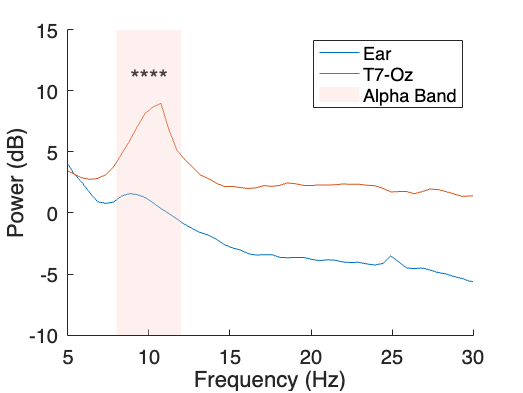

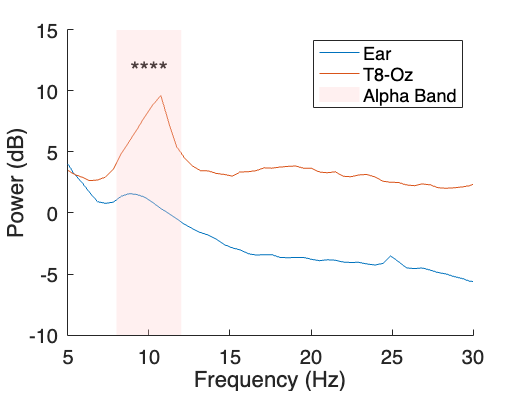

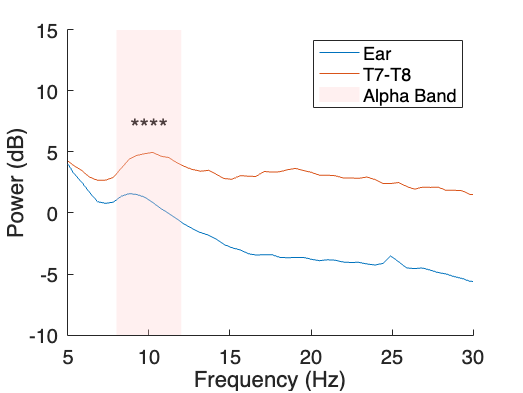

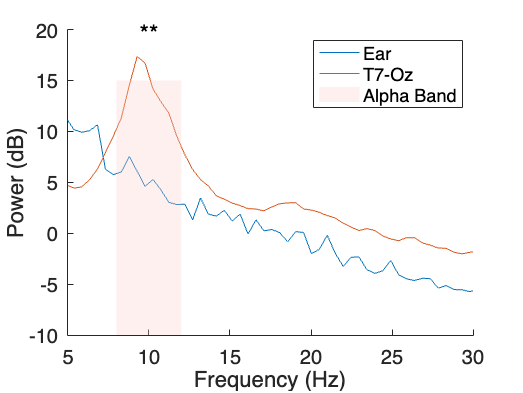

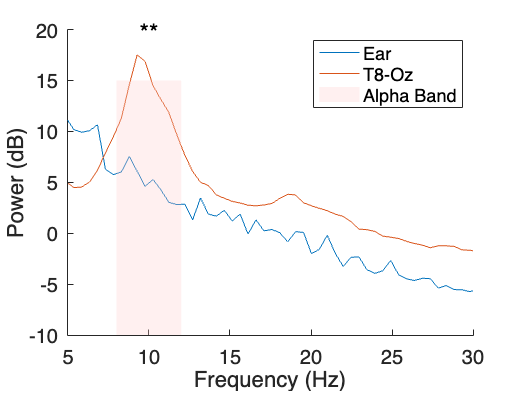

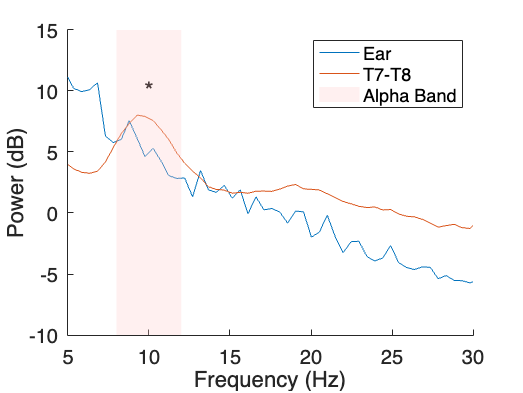

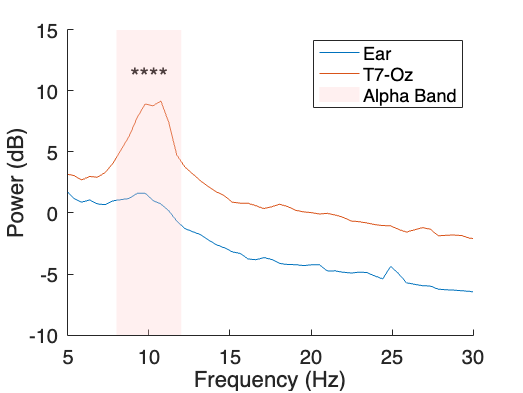

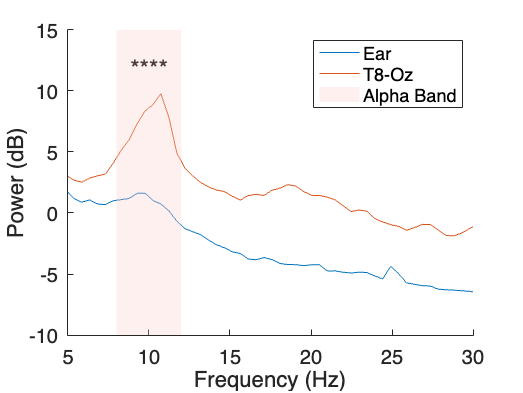

% Initialise structs to store data
num_subjects = length(fooof_results);
group_power_spectrum_peak = struct();
group_fooof_spectrum_peak = struct();
group_aperiodic_exponent = struct();
p_values = struct();
alpha_band = [8, 12];

% Initialise table to store results
results_table = [];


% initialise the structs
for cond = conditions
    cond = cond{1};
    for configuration = configurations
        configuration = configuration{1};
        
        group_power_spectrum_peak.(cond).(configuration) = [];
        group_fooof_spectrum_peak.(cond).(configuration) = [];
        group_aperiodic_exponent.(cond).(configuration) = [];
        p_values.(cond).(configuration) = NaN;
    end
end

%% Extract the data for each subject, condition and configuration
for subject = 1:num_subjects
    for cond = conditions
        cond = cond{1};
        for configuration = configurations
            configuration = configuration{1};
            
            % Store the parameters
            % pre-FOOOF PSD
            psd_original = fooof_results(subject).(configuration).(cond).power_spectrum;
            % post-FOOOF PSD (reconstructed)
            psd_fooofed = fooof_results(subject).(configuration).(cond).fooofed_spectrum;
            % Frequency
            freqs = fooof_results(subject).(configuration).(cond).freqs;
            % Periodic parameters
            periodic_params = fooof_results(subject).(configuration).(cond).gaussian_params; 
            % Aperiodic parameters
            aperiodic_params = fooof_results(subject).(configuration).(cond).aperiodic_params;
            % Aperiodic fit
            psd_aperiodic = fooof_results(subject).(configuration).(cond).ap_fit;
            
            % Extract the peak alpha power in the pre-FOOOF PSD 
            alpha_idx = find(freqs >= 8 & freqs <= 12);
            [max_psd, ~] = max(psd_original(alpha_idx));
            group_power_spectrum_peak.(cond).(configuration) = [group_power_spectrum_peak.(cond).(configuration); max_psd];
            
            % Find the alpha band peak powers post-FOOOF
            alpha_peaks = periodic_params(periodic_params(:,1) >= 8 & periodic_params(:,1) <= 12, :);
            if ~isempty(alpha_peaks)
                [~, max_idx] = max(alpha_peaks(:,2));
                max_alpha_peak = alpha_peaks(max_idx, 2);
                group_fooof_spectrum_peak.(cond).(configuration) = [group_fooof_spectrum_peak.(cond).(configuration); max_alpha_peak];
            else
                % If there is no peak within the alpha band then take the maximum alpha power in the periodic fit
                alpha_idx_fooof = find(freqs >= 8 & freqs <= 12);
                psd_periodic = psd_fooofed - psd_aperiodic;
                max_fooof = max(psd_periodic(alpha_idx_fooof));
                group_fooof_spectrum_peak.(cond).(configuration) = [group_fooof_spectrum_peak.(cond).(configuration); max_fooof];
            end

            %% Extract the aperiodic exponent
            if size(aperiodic_params, 2) == 3
                % Case where 'knee' was used to model FOOOF
                aperiodic_exponent = aperiodic_params(:, 3);
            else 
                % Case where 'fixed' was used to model FOOOF
                aperiodic_exponent = aperiodic_params(:, 2);
            end
            group_aperiodic_exponent.(cond).(configuration) = [group_aperiodic_exponent.(cond).(configuration); aperiodic_exponent];
        end
    end
end


%% Perform the statistical analysis for the peak alpha power
configurations1 = {'T7', 'T8', 'T7T8'};

for cond = conditions
    cond = cond{1};
    for configuration = configurations1
        configuration = configuration{1};
        
        % Get data for scalp configuration
        x = group_power_spectrum_peak.(cond).(configuration);
        % compare to the ear
        y = group_power_spectrum_peak.(cond).ear;

        % Check normality
        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            % Perform repective test based on normality
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            % Store p value
            p_values.(cond).(configuration) = p;
            
            % Calculate the mean and standard deviation for both configurations
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            % store results in table
            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
            
            % Plot the PSD for ear and scalp configuration to obtain a
            % graphical representation of the difference in peak alpha
            % power between the two configurations
            figure;
            hold on;
            % ear
            plot(fooof_avg_results.ear.(cond).freqs, fooof_avg_results.ear.(cond).power_spectrum, 'DisplayName', 'Ear');
            
            if strcmp(configuration, 'T7')
                display_name = 'T7-Oz';
            elseif strcmp(configuration, 'T8')
                display_name = 'T8-Oz';
            elseif strcmp(configuration, 'T7T8')
                display_name = 'T7-T8';
            else
                % ear
                display_name = configuration;
            end

            % Plot scalp configuration
            plot(fooof_avg_results.(configuration).(cond).freqs, fooof_avg_results.(configuration).(cond).power_spectrum, 'DisplayName', display_name);
            
            % Find the alpha band indice
            alpha_idx_ear = fooof_avg_results.ear.(cond).freqs >= alpha_band(1) & fooof_avg_results.ear.(cond).freqs <= alpha_band(2);
            alpha_idx_config = fooof_avg_results.(configuration).(cond).freqs >= alpha_band(1) & fooof_avg_results.(configuration).(cond).freqs <= alpha_band(2);
            
            % Add asterisks for significant difference on the figure
            if p < 0.0001
                asterisks = '****';
            elseif p < 0.001
                asterisks = '***';
            elseif p < 0.01
                asterisks = '**';
            elseif p < 0.05
                asterisks = '*';
            else
                asterisks = '';
            end
            
            % Position asterisks
            if ~isempty(asterisks)
                % Find the maximum power value within the alpha band
                max_power_in_alpha = max([max(fooof_avg_results.ear.(cond).power_spectrum(alpha_idx_ear)), ...
                                          max(fooof_avg_results.(configuration).(cond).power_spectrum(alpha_idx_config))]);
                                text(mean(alpha_band), max_power_in_alpha + 1, asterisks, ...
                    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 18, 'Color', 'black');
            end
           
            % Emphasise the alpha band
            alpha_x = [alpha_band(1), alpha_band(2), alpha_band(2), alpha_band(1)]; 
            alpha_y = [-10, -10, 15, 15]; 
            fill(alpha_x, alpha_y, [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'DisplayName', 'Alpha Band'); 
            xlabel('Frequency (Hz)');
            ylabel('Power (dB)');
            legend show;
            xlim([5 30]);
            set(gca, 'FontSize', 15);  
            % save the figure
            print(['Original_Average_Ear_vs_' configuration '_' cond '.tif'], '-dtiff', '-r600');           

        end
    end
end


%% Display the results table
disp('Statistical Analysis between Pre-FOOOF PSD Alpha Peaks: Ear vs other (dB):')

Statistical Analysis between Pre-FOOOF PSD Alpha Peaks: Ear vs other (dB):


results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Mean_Site_Alpha_Peak', 'Std_Site_Alpha_Peak', 'Mean_Ear_Alpha_Peak', 'Std_Ear_Alpha_Peak', 'Site_Alpha_Peak (dB)', 'Ear_Alpha_Peak (dB)', 'Test_Type'});
disp(results_table);

    Condition      Site       P_Value      Num_Subjects    Mean_Site_Alpha_Peak    Std_Site_Alpha_Peak    Mean_Ear_Alpha_Peak    Std_Ear_Alpha_Peak                                                                                          Site_Alpha_Peak (dB)                                                                                                                                                                                  Ear_Alpha_Peak (dB)                                                                                             Test_Type  
    _________    ________    __________    ____________    ____________________    ___________________    ___________________    


%% Show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (dB) (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

--- Significant Results (dB) (p < 0.05) ---


    Condition      Site       P_Value      Num_Subjects    Mean_Site_Alpha_Peak    Std_Site_Alpha_Peak    Mean_Ear_Alpha_Peak    Std_Ear_Alpha_Peak                                                                                          Site_Alpha_Peak (dB)                                                                                                                                                                                  Ear_Alpha_Peak (dB)                                                                                             Test_Type  
    _________    ________    __________    ____________    ____________________    ___________________    ___________________    

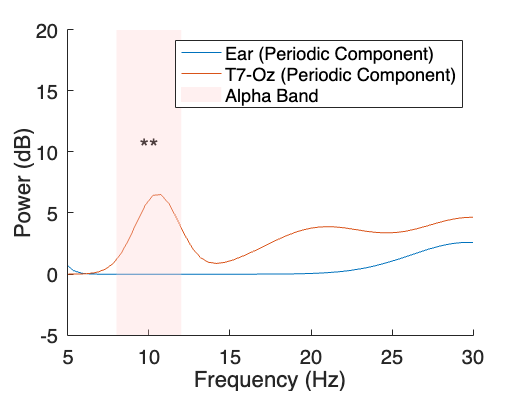

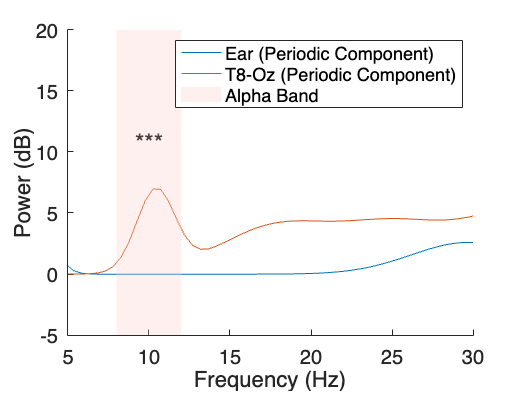

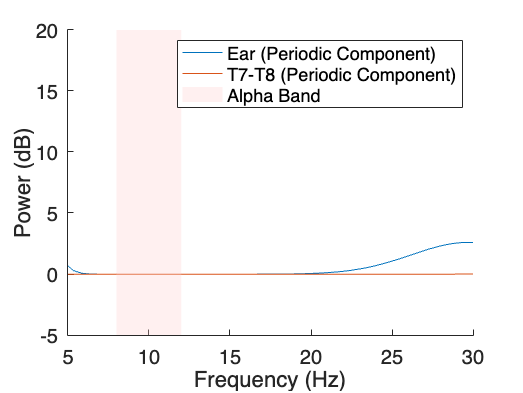

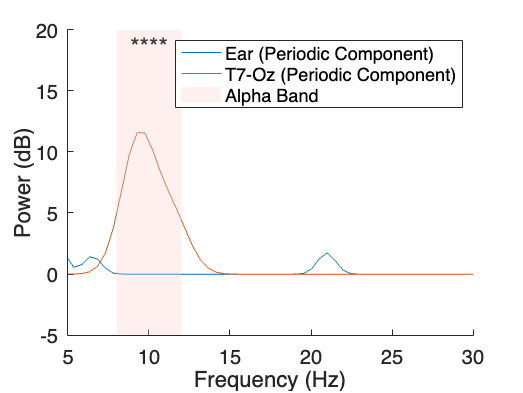

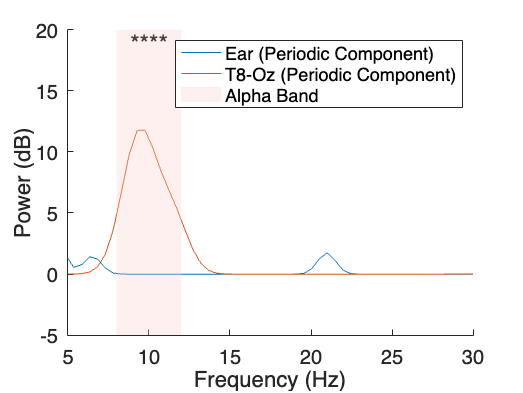

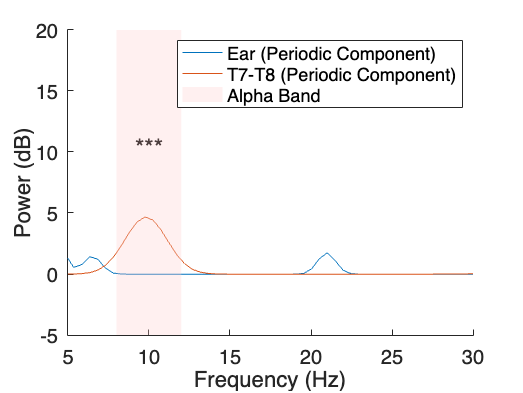

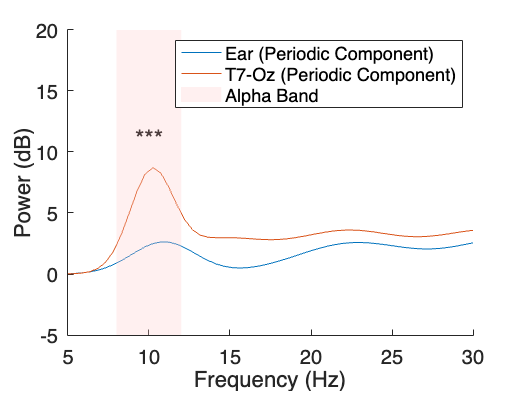

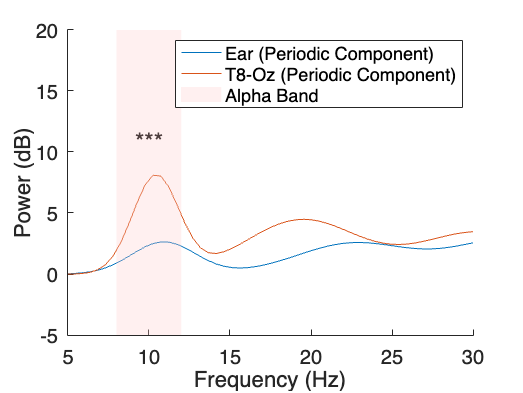


%%%%%%%% Repeat analysis for FOOOFED Spectrum

results_table = {}; 

for cond = conditions
    cond = cond{1};
    for configuration = configurations1
        configuration = configuration{1};
        
        x = group_fooof_spectrum_peak.(cond).(configuration);
        y = group_fooof_spectrum_peak.(cond).ear;

        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;
            
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
            
            % Plotting
            figure;
            hold on;
            
            % Extract of the FOOOFed spectrum, aperiodic fit, and periodic component
            fooof_spectrum_ear = fooof_avg_results.ear.(cond).fooofed_spectrum;
            aperiodic_fit_ear = fooof_avg_results.ear.(cond).ap_fit;
            periodic_fit_ear = fooof_spectrum_ear - aperiodic_fit_ear;
            
            fooof_spectrum_configuration = fooof_avg_results.(configuration).(cond).fooofed_spectrum;
            aperiodic_fit_configuration = fooof_avg_results.(configuration).(cond).ap_fit;
            periodic_fit_configuration = fooof_spectrum_configuration - aperiodic_fit_configuration;
            
            % Plot Ear data
            plot(fooof_avg_results.ear.(cond).freqs, periodic_fit_ear, 'DisplayName', 'Ear (Periodic Component)');
            
            if strcmp(configuration, 'T7')
                display_name = 'T7-Oz';
            elseif strcmp(configuration, 'T8')
                display_name = 'T8-Oz';
            elseif strcmp(configuration, 'T7T8')
                display_name = 'T7-T8';
            else
                % ear
                display_name = configuration; 
            end
            % plot scalp configuration
            plot(fooof_avg_results.(configuration).(cond).freqs, periodic_fit_configuration, 'DisplayName', [display_name ' (Periodic Component)']);
            
            % Find alpha band indices
            alpha_idx_ear = fooof_avg_results.ear.(cond).freqs >= alpha_band(1) & fooof_avg_results.ear.(cond).freqs <= alpha_band(2);
            alpha_idx_config = fooof_avg_results.(configuration).(cond).freqs >= alpha_band(1) & fooof_avg_results.(configuration).(cond).freqs <= alpha_band(2);
            
            % Add asterisks for significant difference
            if p < 0.0001
                asterisks = '****';
            elseif p < 0.001
                asterisks = '***';
            elseif p < 0.01
                asterisks = '**';
            elseif p < 0.05
                asterisks = '*';
            else
                asterisks = '';
            end
            
            % Position the asterisks
            if ~isempty(asterisks)
                max_power_in_alpha = max([max(fooof_spectrum_ear(alpha_idx_ear)), ...
                                          max(fooof_spectrum_configuration(alpha_idx_config))]);
                                text(mean(alpha_band), max_power_in_alpha + 1, asterisks, ...
                    'HorizontalAlignment', 'center', ...
                    'VerticalAlignment', 'bottom', ...
                    'FontSize', 18, ...
                    'Color', 'black');
            end
            
            % Emphasise the alpha band
            alpha_x = [alpha_band(1), alpha_band(2), alpha_band(2), alpha_band(1)]; 
            alpha_y = [-5, -5, 20, 20]; 
            fill(alpha_x, alpha_y, [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'DisplayName', 'Alpha Band'); 
            xlabel('Frequency (Hz)');
            ylabel('Power (dB)');
            legend show;
            xlim([5 30]);
            set(gca, 'FontSize', 15);  
            % save figure
            print(['FOOOFed_Average_Ear_vs_' configuration '_' cond '.tif'], '-dtiff', '-r600');
       
        end
    end
end


%% Display results 
disp('Statistical Analysis between post-FOOOF  PSD Alpha Peaks: Ear vs other (dB):')

Statistical Analysis between post-FOOOF  PSD Alpha Peaks: Ear vs other (dB):


results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Mean_Site_Periodic_Alpha_Peak', 'Std_Site_Periodic_Alpha_Peak', 'Mean_Ear_Periodic_Alpha_Peak', 'Std_Ear_Periodic_Alpha_Peak', 'Site_Periodic_Alpha_Peak (dB)', 'Ear_Periodic_Alpha_Peak (dB)', 'Test_Type'});
disp(results_table);

    Condition      Site       P_Value      Num_Subjects    Mean_Site_Periodic_Alpha_Peak    Std_Site_Periodic_Alpha_Peak    Mean_Ear_Periodic_Alpha_Peak    Std_Ear_Periodic_Alpha_Peak                                                                                      Site_Periodic_Alpha_Peak (dB)                                                                                                                                                                 Ear_Periodic_Alpha_Peak (dB)                                                                                Test_Type  
    _________    ________    __________    ____________    _____________________________    ____________________________    


%% Show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (dB) (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

--- Significant Results (dB) (p < 0.05) ---


    Condition      Site       P_Value      Num_Subjects    Mean_Site_Periodic_Alpha_Peak    Std_Site_Periodic_Alpha_Peak    Mean_Ear_Periodic_Alpha_Peak    Std_Ear_Periodic_Alpha_Peak                                                                                      Site_Periodic_Alpha_Peak (dB)                                                                                                                                                                 Ear_Periodic_Alpha_Peak (dB)                                                                                Test_Type  
    _________    ________    __________    ____________    _____________________________    ____________________________    

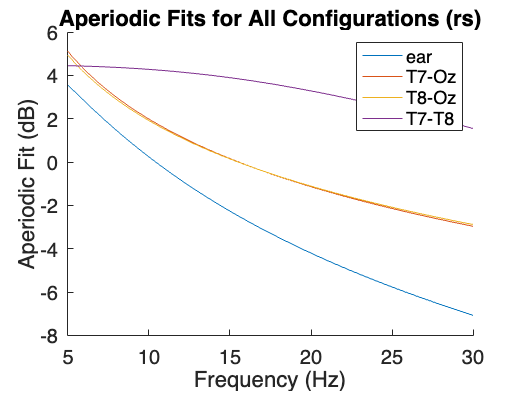

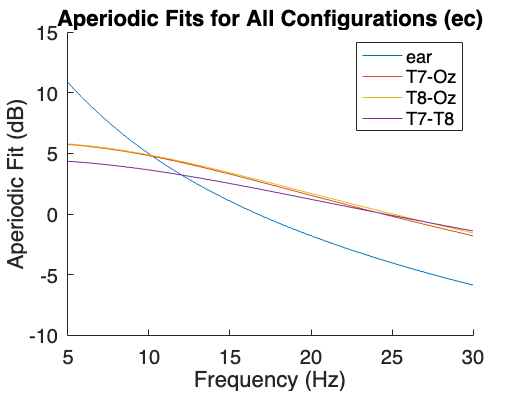

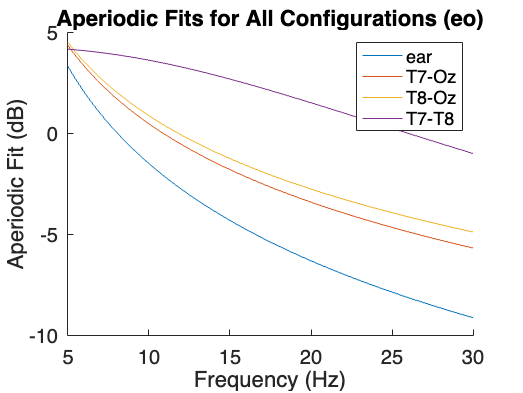


%%%%%%%%% Repeat analysis for aperiodic exponent

results_table = {}; 

for cond = conditions
    cond = cond{1};
    
    % Create a new figure for each condition
    figure;
    hold on;
    
    configurations = {'ear', 'T7', 'T8', 'T7T8'}; 
    for configuration = configurations
        configuration = configuration{1};
        
        x = group_aperiodic_exponent.(cond).(configuration);
        y = group_aperiodic_exponent.(cond).ear;

        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;
            
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
            
            % Extract aperiodic fit for the current configuration and condition
            aperiodic_fit = fooof_avg_results.(configuration).(cond).ap_fit;
            freqs = fooof_avg_results.(configuration).(cond).freqs;
            
            if strcmp(configuration, 'T7')
                display_name = 'T7-Oz';
            elseif strcmp(configuration, 'T8')
                display_name = 'T8-Oz';
            elseif strcmp(configuration, 'T7T8')
                display_name = 'T7-T8';
            else
                % ear
                display_name = configuration; 
            end

            % Plot the aperiodic fit
            plot(freqs, aperiodic_fit, 'DisplayName', display_name);

        end
    end
    
    title(['Aperiodic Fits for All Configurations (' cond ')']);
    xlabel('Frequency (Hz)');
    ylabel('Aperiodic Fit (dB)');
    legend show;
    xlim([5 30]);
    set(gca, 'FontSize', 15);  
    % save figure
    print(['Aperiodic_Fits_' cond '.tif'], '-dtiff', '-r600');            
        
end


%% Display results
disp('Statistical Analysis between Aperiodic exponents:')

Statistical Analysis between Aperiodic exponents:


results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Mean_Site_Aperiodic_Exponent', 'Std_Site_Aperiodic_Exponent', 'Mean_Ear_Aperiodic_Exponent', 'Std_Ear_Aperiodic_Exponent', 'Site_Aperiodic_Exponent', 'Ear_Aperiodic_Exponent', 'Test_Type'});
disp(results_table);

    Condition      Site      P_Value    Num_Subjects    Mean_Site_Aperiodic_Exponent    Std_Site_Aperiodic_Exponent    Mean_Ear_Aperiodic_Exponent    Std_Ear_Aperiodic_Exponent                                                                                         Site_Aperiodic_Exponent                                                                                                                                                                        Ear_Aperiodic_Exponent                                                                                   Test_Type  
    _________    ________    _______    ____________    ____________________________    ___________________________    ___________


%% Show significant differences
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

No significant results found (p < 0.05).




%%%%%%%%%%%% Repeat analysis for SNR 

% pre-FOOOF SNR
snr_original = struct();  
% post-FOOOF SNR
snr_fooofed = struct();   

% Initialise storage structs
for configuration = configurations
    configuration = configuration{1};
    snr_original.(configuration) = [];  
    snr_fooofed.(configuration) = [];   
end

%% Calculate SNRs pre- and post-FOOOF
for subject = 1:num_subjects
    for configuration = configurations
        configuration = configuration{1};
        
        %% Pre-FOOOF PSD
        % Extract alpha power for eyes closed and eyes open 
        psd_ec_original = fooof_results(subject).(configuration).ec.power_spectrum;
        psd_eo_original = fooof_results(subject).(configuration).eo.power_spectrum;
        freqs = fooof_results(subject).(configuration).ec.freqs;  
        
        % Find the alpha band indices
        alpha_idx = find(freqs >= 8 & freqs <= 12);
        
        % Find the average alpha power
        alpha_power_ec_original = mean(psd_ec_original(alpha_idx));
        alpha_power_eo_original = mean(psd_eo_original(alpha_idx));
        
        % Find the SNR
        snr_original.(configuration) = [snr_original.(configuration); alpha_power_ec_original - alpha_power_eo_original];
        
        % Post-FOOOF PSD
        % Extract alpha power for eyes closed and eyes open 
        psd_ec_fooofed = fooof_results(subject).(configuration).ec.fooofed_spectrum - fooof_results(subject).(configuration).ec.ap_fit;
        psd_eo_fooofed = fooof_results(subject).(configuration).eo.fooofed_spectrum - fooof_results(subject).(configuration).eo.ap_fit;
        
        % Find the average alpha power
        alpha_power_ec_fooofed = mean(psd_ec_fooofed(alpha_idx));
        alpha_power_eo_fooofed = mean(psd_eo_fooofed(alpha_idx));
        
        % Find the SNR
        snr_fooofed.(configuration) = [snr_fooofed.(configuration); alpha_power_ec_fooofed - alpha_power_eo_fooofed];
    end
end

%% Compare the SNRs 

%% First look at the pre-FOOOF PSD
% Initialize table for results
snr_comparison_table = [];

% Compare all scalp configurations with the ear
for configuration = configurations1
    configuration = configuration{1};
    
    % Extract the SNR values 
    snr_original_configuration = snr_original.(configuration);
    snr_original_ear = snr_original.ear;  
    
    % Find the average SNR for each
    avg_snr_original_configuration = mean(snr_original_configuration);
    avg_snr_original_ear = mean(snr_original_ear);
    
    % Find their standard deviation
    std_snr_original_configuration = std(snr_original_configuration);
    std_snr_original_ear = std(snr_original_ear);
    
    % Issue displaying them but string works
    snr_original_configuration_str = strjoin(string(snr_original_configuration), ', ');
    snr_original_ear_str = strjoin(string(snr_original_ear), ', ');
    
    % Check their normality
    [h_x, p_x] = swtest(snr_original_configuration);  
    [h_y, p_y] = swtest(snr_original_ear);  
    
    % Perform statistical test based on their normality
    if h_x == 0 && h_y == 0  
        [~, p, ~, stats] = ttest(snr_original_configuration, snr_original_ear);
        test_type = 'Paired t-test';
    else
        [p, ~, stats] = signrank(snr_original_configuration, snr_original_ear);
        test_type = 'Wilcoxon signed-rank test';
    end
    
    % Store the results
    snr_comparison_table = [snr_comparison_table; {configuration, test_type, avg_snr_original_configuration, std_snr_original_configuration, snr_original_configuration_str, avg_snr_original_ear, std_snr_original_ear, snr_original_ear_str, p}];
end

% print the table
disp('Comparison of the ear and scalp configuration Pre-FOOOF SNRs (dB)');

Comparison of the ear and scalp configuration Pre-FOOOF SNRs (dB)


snr_comparison_table = cell2table(snr_comparison_table, 'VariableNames', {'Site', 'Test_Type', 'Avg_SNR_Original_Site', 'Std_SNR_Original_Site', 'SNR_Original_Site', 'Avg_SNR_Original_Ear', 'Std_SNR_Original_Ear', 'SNR_Original_Ear', 'P_Value'});
disp(snr_comparison_table);

      Site                Test_Type              Avg_SNR_Original_Site    Std_SNR_Original_Site                                                               SNR_Original_Site                                                               Avg_SNR_Original_Ear    Std_SNR_Original_Ear                                                                SNR_Original_Ear                                                                 P_Value 
    ________    _____________________________    _____________________    _____________________    _______________________________________________________________________________________________________________________________________    ____________________    ____________________    


%% Show significant results
significant_results = snr_comparison_table(snr_comparison_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (dB) (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

--- Significant Results (dB) (p < 0.05) ---


     Site               Test_Type              Avg_SNR_Original_Site    Std_SNR_Original_Site                                                               SNR_Original_Site                                                               Avg_SNR_Original_Ear    Std_SNR_Original_Ear                                                                SNR_Original_Ear                                                                 P_Value 
    ______    _____________________________    _____________________    _____________________    _______________________________________________________________________________________________________________________________________    ____________________    ____________________    __



%%% Repeat for post-FOOOF SNR

snr_comparison_table = [];

for configuration = configurations1
    configuration = configuration{1};
    
    % Extract SNR values
    snr_fooofed_configuration = snr_fooofed.(configuration);
    snr_fooofed_ear = snr_fooofed.ear;  
    
    % Find average
    avg_snr_fooofed_configuration = mean(snr_fooofed_configuration);
    avg_snr_fooofed_ear = mean(snr_fooofed_ear);
    
    % Find standard deviation
    std_snr_fooofed_configuration = std(snr_fooofed_configuration);
    std_snr_fooofed_ear = std(snr_fooofed_ear);
    
    % Use string to print these later
    snr_fooofed_configuration_str = strjoin(string(snr_fooofed_configuration), ', ');
    snr_fooofed_ear_str = strjoin(string(snr_fooofed_ear), ', ');
    
    % Check normality
    [h_x, p_x] = swtest(snr_fooofed_configuration);  
    [h_y, p_y] = swtest(snr_fooofed_ear);  

    % Perform statistical test
    if h_x == 0 && h_y == 0  
        [~, p, ~, stats] = ttest(snr_fooofed_configuration, snr_fooofed_ear);
        test_type = 'Paired t-test';
    else
        [p, ~, stats] = signrank(snr_fooofed_configuration, snr_fooofed_ear);
        test_type = 'Wilcoxon signed-rank test';
    end
    
    % Store the results 
    snr_comparison_table = [snr_comparison_table; {configuration, test_type, avg_snr_fooofed_configuration, std_snr_fooofed_configuration, snr_fooofed_configuration_str, avg_snr_fooofed_ear, std_snr_fooofed_ear, snr_fooofed_ear_str, p}];
end

% Show the results
disp('Comparison of the ear and scalp configuration Post-FOOOF SNRs (dB)');

Comparison of the ear and scalp configuration Post-FOOOF SNRs (dB)


snr_comparison_table = cell2table(snr_comparison_table, 'VariableNames', {'Site', 'Test_Type', 'Avg_SNR_Fooofed_Site', 'Std_SNR_Fooofed_Site', 'SNR_Fooofed_Site', 'Avg_SNR_Fooofed_Ear', 'Std_SNR_Fooofed_Ear', 'SNR_Fooofed_Ear', 'P_Value'});
disp(snr_comparison_table);

      Site          Test_Type        Avg_SNR_Fooofed_Site    Std_SNR_Fooofed_Site                                                            SNR_Fooofed_Site                                                            Avg_SNR_Fooofed_Ear    Std_SNR_Fooofed_Ear                                                               SNR_Fooofed_Ear                                                                 P_Value 
    ________    _________________    ____________________    ____________________    ________________________________________________________________________________________________________________________________    ___________________    ___________________    ______________________________________________


%% Show significant results 
significant_results = snr_comparison_table(snr_comparison_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (dB) (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

--- Significant Results (dB) (p < 0.05) ---


     Site         Test_Type        Avg_SNR_Fooofed_Site    Std_SNR_Fooofed_Site                                                         SNR_Fooofed_Site                                                         Avg_SNR_Fooofed_Ear    Std_SNR_Fooofed_Ear                                                               SNR_Fooofed_Ear                                                                 P_Value 
    ______    _________________    ____________________    ____________________    __________________________________________________________________________________________________________________________    ___________________    ___________________    ______________________________________________________________

## Section 5: Continuation of Implementation of Analysis 2

This section computes the correlation coefficient to identify the scalp configuration which correlates best with the ear.

% Initialize table to store 
results_table = table('Size', [0, 6], ...
    'VariableTypes', {'string', 'string', 'string', 'double', 'double', 'string'}, ...
    'VariableNames', {'Analysis', 'Condition', 'Site', 'Correlation', 'PValue', 'Method'});

%%%% Analysis for pre-FOOOF peak alpha power
analysis_name = 'PreFOOOF_Peak_Alpha_Power'; 

% loop through all conditions
for cond = conditions
    cond = cond{1};
    
    % extract pre-FOOOF PSD for the ear
    ear_data_alpha = group_power_spectrum_peak.(cond).('ear');
    
    % compare to scalp configurations
    for configuration = configurations
        configuration = configuration{1};
        
        if ~strcmp(configuration, 'ear')
            configuration_data_alpha = group_power_spectrum_peak.(cond).(configuration);
            
            % Check normality
            if length(ear_data_alpha) == length(configuration_data_alpha)
                is_ear_normal = swtest(ear_data_alpha) == 0;
                is_configuration_normal = swtest(configuration_data_alpha) == 0;
                
                % Perform correlation analysis based on normality
                if is_ear_normal && is_configuration_normal
                    method = 'Pearson';
                else
                    method = 'Spearman';
                end
                
                [corr_coeff, p_val] = corr(ear_data_alpha, configuration_data_alpha, 'Type', method);
                
                % Add results to the table 
                new_row = {analysis_name, cond, configuration, corr_coeff, p_val, method};
                results_table = [results_table; new_row];
            
            end
        end
    end
end

%%% ANALYSIS OF THIS TABLE SHOWED THAT THERE WAS A COMBINATION OF NORMAL
%%% AND NON-NORMAL DATASETS. AS PER PAZUELO ET AL (2024), IT IS SUGGESTED
%%% TO USE SPEARMAN CORRELATION FOR THIS. 
%%% Print the new rows accounting for this
analysis_name = 'PreFOOOF_Peak_Alpha_Power_Spearman'; 

% loop through all conditions
for cond = conditions
    cond = cond{1};
    
    % extract pre-FOOOF PSD for the ear
    ear_data_alpha = group_power_spectrum_peak.(cond).('ear');
    
    % compare to scalp configurations
    for configuration = configurations
        configuration = configuration{1};
        
        if ~strcmp(configuration, 'ear')
            configuration_data_alpha = group_power_spectrum_peak.(cond).(configuration);
            
            method = 'Spearman';
            
            
            [corr_coeff, p_val] = corr(ear_data_alpha, configuration_data_alpha, 'Type', method);
            
            % Add results to the table 
            new_row = {analysis_name, cond, configuration, corr_coeff, p_val, method};
            results_table = [results_table; new_row];
            
        end
    end
end


%%%%%% Repeat analysis for the post-FOOOF peak alpha power
analysis_name = 'PostFOOOF_Peak_Alpha_Power'; 

for cond = conditions
    cond = cond{1};
    
    ear_data_alpha = group_fooof_spectrum_peak.(cond).('ear');
    
    for configuration = configurations
        configuration = configuration{1};
        
        if ~strcmp(configuration, 'ear')
            configuration_data_alpha = group_fooof_spectrum_peak.(cond).(configuration);
            
            if length(ear_data_alpha) == length(configuration_data_alpha)
                is_ear_normal = swtest(ear_data_alpha) == 0;
                is_configuration_normal = swtest(configuration_data_alpha) == 0;
                
                if is_ear_normal && is_configuration_normal
                    method = 'Pearson';
                else
                    method = 'Spearman';
                end
                
                [corr_coeff, p_val] = corr(ear_data_alpha, configuration_data_alpha, 'Type', method);
                
                new_row = {analysis_name, cond, configuration, corr_coeff, p_val, method};
                results_table = [results_table; new_row];
            
            end
        end
    end
end

%%% ANALYSIS OF THIS TABLE SHOWED THAT THERE WAS A COMBINATION OF NORMAL
%%% AND NON-NORMAL DATASETS. AS PER PAZUELO ET AL (2024), IT IS SUGGESTED
%%% TO USE SPEARMAN CORRELATION FOR THIS. 
%%% Print the new rows accounting for this
analysis_name = 'PostFOOOF_Peak_Alpha_Power_Spearman'; 

for cond = conditions
    cond = cond{1};
    
    ear_data_alpha = group_fooof_spectrum_peak.(cond).('ear');
    
    for configuration = configurations
        configuration = configuration{1};
        
        if ~strcmp(configuration, 'ear')
            configuration_data_alpha = group_fooof_spectrum_peak.(cond).(configuration);
            
            method = 'Spearman';
            
            
            [corr_coeff, p_val] = corr(ear_data_alpha, configuration_data_alpha, 'Type', method);
            
            new_row = {analysis_name, cond, configuration, corr_coeff, p_val, method};
            results_table = [results_table; new_row];
            
        end
    end
end

%%%%%%% Repeat analysis for  Aperiodic Exponent
analysis_name = 'Aperiodic_Exponent'; 

for cond = conditions
    cond = cond{1};
    
    ear_data_alpha = group_aperiodic_exponent.(cond).('ear');
    
    for configuration = configurations
        configuration = configuration{1};
        
        if ~strcmp(configuration, 'ear')
            configuration_data_alpha = group_aperiodic_exponent.(cond).(configuration);
            
            if length(ear_data_alpha) == length(configuration_data_alpha)
                is_ear_normal = swtest(ear_data_alpha) == 0;
                is_configuration_normal = swtest(configuration_data_alpha) == 0;
                
                if is_ear_normal && is_configuration_normal
                    method = 'Pearson';
                else
                    method = 'Spearman';
                end
                
                [corr_coeff, p_val] = corr(ear_data_alpha, configuration_data_alpha, 'Type', method);
                
                new_row = {analysis_name, cond, configuration, corr_coeff, p_val, method};
                results_table = [results_table; new_row];
            
            end
        end
    end
end

%%% ANALYSIS OF THIS TABLE SHOWED THAT THERE WAS A COMBINATION OF NORMAL
%%% AND NON-NORMAL DATASETS. AS PER PAZUELO ET AL (2024), IT IS SUGGESTED
%%% TO USE SPEARMAN CORRELATION FOR THIS. 
%%% Print the new rows accounting for this

analysis_name = 'Aperiodic_Exponent_Spearman'; 

for cond = conditions
    cond = cond{1};
    
    ear_data_alpha = group_aperiodic_exponent.(cond).('ear');
    
    for configuration = configurations
        configuration = configuration{1};
        
        if ~strcmp(configuration, 'ear')
            configuration_data_alpha = group_aperiodic_exponent.(cond).(configuration);
            
            method = 'Spearman';
            
            [corr_coeff, p_val] = corr(ear_data_alpha, configuration_data_alpha, 'Type', method);
            
            new_row = {analysis_name, cond, configuration, corr_coeff, p_val, method};
            results_table = [results_table; new_row];

        end
    end
end

%% Show the final table
disp(results_table);

                  Analysis                   Condition     Site     Correlation      PValue        Method  
    _____________________________________    _________    ______    ___________    __________    __________

    "PreFOOOF_Peak_Alpha_Power"                "rs"       "T7"         0.33549        0.22154    "Pearson" 
    "PreFOOOF_Peak_Alpha_Power"                "rs"       "T8"         0.27745        0.31674    "Pearson" 
    "PreFOOOF_Peak_Alpha_Power"                "rs"       "T7T8"        0.5893       0.020791    "Pearson" 
    "PreFOOOF_Peak_Alpha_Power"                "ec"       "T7"         0.14286        0.61144    "Spearman"
    "PreFOOOF_Peak_Alpha_Power"                "ec"       "T8"            0.25        0.36773    "Spearman"
    "PreFOOOF_Peak_Alpha_Power"        

## Section 6: Implementation of Analysis 3 

This section provides an analysis between the scalp hemispheric configurations for peak alpha power, SNR and the aperiodic exponent. 

%% Initialise structs to store data
num_subjects = length(fooof_results);
group_power_spectrum_peak1 = struct();
group_fooof_spectrum_peak1 = struct();
p_values = struct();

% Initialize table for results
results_table = [];

% Initialise the struct
for cond = conditions
    cond = cond{1};
    for configuration = configurations
        configuration = configuration{1};
        
        group_power_spectrum_peak1.(cond).(configuration) = [];
        group_fooof_spectrum_peak1.(cond).(configuration) = [];
        group_aperiodic_exponent1.(cond).(configuration) = [];
        p_values.(cond).(configuration) = NaN;
    end
end

%% Extract the data for each subject, condition and configuration
for subject = 1 : num_subjects
    for cond = conditions
        cond = cond{1};
        for configuration = configurations
            configuration = configuration{1};
            
            % Extract pre-FOOOF PSD
            psd_original = fooof_results(subject).(configuration).(cond).power_spectrum;
            % FOOOF reconstructed PSD
            psd_fooofed = fooof_results(subject).(configuration).(cond).fooofed_spectrum;
            % Frequency
            freqs = fooof_results(subject).(configuration).(cond).freqs;
            % Periodic Parameters
            periodic_params = fooof_results(subject).(configuration).(cond).gaussian_params; 
            % Aperiodic Parameters
            aperiodic_params = fooof_results(subject).(configuration).(cond).aperiodic_params;
            % aperiodic fit
            psd_aperiodic = fooof_results(subject).(configuration).(cond).ap_fit;
            
            % Extract peak alpha power of the pre-FOOOF PSD
            alpha_idx = find(freqs >= 8 & freqs <= 12);
            [max_psd, ~] = max(psd_original(alpha_idx));
            group_power_spectrum_peak1.(cond).(configuration) = [group_power_spectrum_peak1.(cond).(configuration); max_psd];
            
            % Find the alpha band peak powers post-FOOOF
            alpha_peaks = periodic_params(periodic_params(:,1) >= 8 & periodic_params(:,1) <= 12, :);
            if ~isempty(alpha_peaks)
                [~, max_idx] = max(alpha_peaks(:,2));
                max_alpha_peak = alpha_peaks(max_idx, 2);
                group_fooof_spectrum_peak1.(cond).(configuration) = [group_fooof_spectrum_peak.(cond).(configuration); max_alpha_peak];
            else
                % If there is no peak within the alpha band then take the maximum alpha power in the periodic fit
                alpha_idx_fooof = find(freqs >= 8 & freqs <= 12);
                psd_periodic = psd_fooofed - psd_aperiodic;
                max_fooof = max(psd_periodic(alpha_idx_fooof));
                group_fooof_spectrum_peak1.(cond).(configuration) = [group_fooof_spectrum_peak.(cond).(configuration); max_fooof];
            end

            %% Extract the aperiodic exponents

            if size(aperiodic_params, 2) == 3
                % case of 'knee' to model FOOOF
                aperiodic_exponent = aperiodic_params(:, 3);
            else 
                % case of 'fixed' to model FOOOOF
                aperiodic_exponent = aperiodic_params(:, 2);
            end
            group_aperiodic_exponent1.(cond).(configuration) = [group_aperiodic_exponent1.(cond).(configuration); aperiodic_exponent];

        end
    end
end

% only compare T7-Oz to T8-Oz
configurations1 = {'T7'};

%%% pre-FOOOF peak alpha power
%% Perform statistical analysis for all conditions 
for cond = conditions
    cond = cond{1};
    for configuration = configurations1
        configuration = configuration{1};
        
        x = group_power_spectrum_peak1.(cond).(configuration);
        y = group_power_spectrum_peak1.(cond).T8;

        % check normality
        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            % performed respective statistical test
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            % store results
            p_values.(cond).(configuration) = p;
            results_table = [results_table; {cond, configuration, p, numel(x), num2str(x'), num2str(y'), test_type}];
        
        end
    end
end

%% Show table
disp('Statistical Analysis between Original PSD Alpha Peaks  T7-Oz and T8-Oz (dB):')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'T7-Oz Alpha Peak (dB)', 'T8-Oz Alpha Peak (dB)', 'Test_Type'});
disp(results_table);

%% Show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

%%% Repeat analysis for post-FOOOF peak alpha power

results_table = {};  

for cond = conditions
    cond = cond{1};
    for configuration = configurations1
        configuration = configuration{1};
        
        x = group_fooof_spectrum_peak1.(cond).(configuration);
        y = group_fooof_spectrum_peak1.(cond).T8;

        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;
            results_table = [results_table; {cond, configuration, p, numel(x), num2str(x'), num2str(y'), test_type}];
        
        end
    end
end

%% Show results
disp('Statistical Analysis between Periodic Activity PSD Alpha Peaks T7-Oz and T8-Oz (dB):')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'T7-Oz Alpha Peak (dB)', 'T8-Oz Alpha Peak (dB)', 'Test_Type'});
disp(results_table);


%% show signifcant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

%%% repeat analysis for the aperiodic exponent

results_table = {};  

for cond = conditions
    cond = cond{1};
    for configuration = configurations1
        configuration = configuration{1};
        
        x = group_aperiodic_exponent1.(cond).(configuration);
        y = group_aperiodic_exponent1.(cond).T8;

        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;
            results_table = [results_table; {cond, configuration, p, numel(x), num2str(x'), num2str(y'), test_type}];
        else
            p_values.(cond).(configuration) = NaN;
            fprintf('Not enough data for comparison for %s, %s.\n', cond, configuration);
        end
    end
end


%% show results
disp('Statistical Analysis between Aperiodic exponents T7-Oz and T8-Oz:')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'T7-Oz Aperiodic Exponent', 'T8-Oz Aperiodic exponent', 'Test_Type'});
disp(results_table);

%% show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

%%%% repeat analysis for SNR
% pre-FOOOF SNR
snr_original = struct();  
% post-FOOOF SNR
snr_fooofed = struct();   

% initialise structs
for configuration = configurations
    configuration = configuration{1};
    snr_original.(configuration) = [];  
    snr_fooofed.(configuration) = [];   
end


%% Calculate the SNR for pre- and post-FOOOF
for subject = 1:num_subjects
    for configuration = configurations
        configuration = configuration{1};
        
        %% pre-FOOOF PSD
        % Extract alpha power for eyes closed aand eyes open
        psd_ec_original = fooof_results(subject).(configuration).ec.power_spectrum;
        psd_eo_original = fooof_results(subject).(configuration).eo.power_spectrum;
        freqs = fooof_results(subject).(configuration).ec.freqs;  
        
        % Find alpha band indices 
        alpha_idx = find(freqs >= 8 & freqs <= 12);
        
        % Find average alpha powers of EC and EO
        alpha_power_ec_original = mean(psd_ec_original(alpha_idx));
        alpha_power_eo_original = mean(psd_eo_original(alpha_idx));
        
        % Find SNR 
        snr_original.(configuration) = [snr_original.(configuration); alpha_power_ec_original - alpha_power_eo_original];
        
        % Post-FOOOF PSD
        % Extract alpha power for eyes closed and eyes open 
        psd_ec_fooofed = fooof_results(subject).(configuration).ec.fooofed_spectrum - fooof_results(subject).(configuration).ec.ap_fit;
        psd_eo_fooofed = fooof_results(subject).(configuration).eo.fooofed_spectrum - fooof_results(subject).(configuration).eo.ap_fit;
        
        % Find the average alpha power
        alpha_power_ec_fooofed = mean(psd_ec_fooofed(alpha_idx));
        alpha_power_eo_fooofed = mean(psd_eo_fooofed(alpha_idx));
        
        % Find the SNR
        snr_fooofed.(configuration) = [snr_fooofed.(configuration); alpha_power_ec_fooofed - alpha_power_eo_fooofed];
    end
end


%% Perform statistical analysis for SNR
% Pre-FOOOF SNR analysis:
snr_comparison_table = [];

for configuration = configurations1
    configuration = configuration{1};
    
    % Extract SNR values
    snr_original_configuration = snr_original.(configuration);
    snr_original_T8 = snr_original.T8;  
    
    % Calculate average SNR
    avg_snr_original_configuration = mean(snr_original_configuration);
    avg_snr_original_T8 = mean(snr_original_T8);
    
    % Calculate standard deviation
    std_snr_original_configuration = std(snr_original_configuration);
    std_snr_original_T8 = std(snr_original_T8);
    
    % Use string to show these in table
    snr_original_configuration_str = strjoin(string(snr_original_configuration), ', ');
    snr_original_T8_str = strjoin(string(snr_original_T8), ', ');
    
    % Check normality
    [h_x, p_x] = swtest(snr_original_configuration);  
    [h_y, p_y] = swtest(snr_original_T8);  
    
    % Perform statistical test based on normality
    if h_x == 0 && h_y == 0  
        [~, p, ~, stats] = ttest(snr_original_configuration, snr_original_T8);
        test_type = 'Paired t-test';
    else
        [p, ~, stats] = signrank(snr_original_configuration, snr_original_T8);
        test_type = 'Wilcoxon signed-rank test';
    end
    
    % Store the results
    snr_comparison_table = [snr_comparison_table; {configuration, test_type, avg_snr_original_configuration, std_snr_original_configuration, snr_original_configuration_str, avg_snr_original_T8, std_snr_original_T8, snr_original_T8_str, p}];
end

% show the results
disp('Comparison of pre-FOOOF SNR of T7-Oz and T8-Oz (dB):');
snr_comparison_table = cell2table(snr_comparison_table, 'VariableNames', {'Site', 'Test_Type', 'Avg_SNR_T7-Oz_Site', 'Std_SNR', 'SNR_T7-OZ_Site', 'Avg_SNR_T8-Oz', 'Std_SNR_T8-Oz', 'SNR_T8-Oz', 'P_Value'});
disp(snr_comparison_table);

%% show significant results
significant_results = snr_comparison_table(snr_comparison_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end


%%% repeat for SNR post-FOOOF
snr_comparison_table = [];

for configuration = configurations1
    configuration = configuration{1};
    
    snr_fooofed_configuration = snr_fooofed.(configuration);
    snr_fooofed_T8 = snr_fooofed.T8;  

    avg_snr_fooofed_configuration = mean(snr_fooofed_configuration);
    avg_snr_fooofed_T8 = mean(snr_fooofed_T8);
    
    std_snr_fooofed_configuration = std(snr_fooofed_configuration);
    std_snr_fooofed_T8 = std(snr_fooofed_T8);
    
    snr_fooofed_configuration_str = strjoin(string(snr_fooofed_configuration), ', ');
    snr_fooofed_T8_str = strjoin(string(snr_fooofed_T8), ', ');
    
    [h_x, p_x] = swtest(snr_fooofed_configuration);  
    [h_y, p_y] = swtest(snr_fooofed_T8);  
    
    if h_x == 0 && h_y == 0  
        [~, p, ~, stats] = ttest(snr_fooofed_configuration, snr_fooofed_T8);
        test_type = 'Paired t-test';
    else
        [p, ~, stats] = signrank(snr_fooofed_configuration, snr_fooofed_T8);
        test_type = 'Wilcoxon signed-rank test';
    end
    
    snr_comparison_table = [snr_comparison_table; {configuration, test_type, avg_snr_fooofed_configuration, std_snr_fooofed_configuration, snr_fooofed_configuration_str, avg_snr_fooofed_T8, std_snr_fooofed_T8, snr_fooofed_T8_str, p}];
end

% show results
disp('Comparison of post-FOOOF SNR of T7-Oz and T8-Oz (dB):');
snr_comparison_table = cell2table(snr_comparison_table, 'VariableNames', {'Site', 'Test_Type', 'Avg_SNR_T7-Oz_Site', 'Std_SNR', 'SNR_T7-OZ_Site', 'Avg_SNR_T8-Oz', 'Std_SNR_T8-Oz', 'SNR_T8-Oz', 'P_Value'});
disp(snr_comparison_table);

%% show significant results
significant_results = snr_comparison_table(snr_comparison_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end



## Section 7: Continuation of Analysis 3

This section computes the average between the two scalp hemispheric configurations (T7-Oz and T8-Oz) for periodic and aperiodic activities after validating that there was no significant difference between these for periodic and aperiodic metrics.

% Initialize structs to store values
group_power_spectrum_peak_avgT7T8 = struct();
group_fooof_spectrum_peak_avgT7T8 = struct();
group_aperiodic_exponent_avgT7T8 = struct();
snr_original_avgT7T8 = struct();
snr_fooofed_avgT7T8 = struct();

% Loop through all conditions 
for cond = conditions
    cond = cond{1};

        % find the average pre-FOOOF peak alpha power
        power_t7 = group_power_spectrum_peak1.(cond).T7;
        power_t8 = group_power_spectrum_peak1.(cond).T8;
        
        % Compute the average peak alpha power
        if numel(power_t7) > 0 && numel(power_t8) > 0
            group_power_spectrum_peak_avgT7T8.(cond) = (power_t7 + power_t8) / 2;
        else
            group_power_spectrum_peak_avgT7T8.(cond) = NaN;
        end
        
        % Compute the average for post-FOOOF peak alpha power
        fooof_t7 = group_fooof_spectrum_peak1.(cond).T7;
        fooof_t8 = group_fooof_spectrum_peak1.(cond).T8;
        
        if numel(fooof_t7) > 0 && numel(fooof_t8) > 0
            group_fooof_spectrum_peak_avgT7T8.(cond) = (fooof_t7 + fooof_t8) / 2;
        else
            group_fooof_spectrum_peak_avgT7T8.(cond) = NaN;
        end
        
        % Compute the average for aperiodic exponent
        exponent_t7 = group_aperiodic_exponent1.(cond).T7;
        exponent_t8 = group_aperiodic_exponent1.(cond).T8;
        
        if numel(exponent_t7) > 0 && numel(exponent_t8) > 0
            group_aperiodic_exponent_avgT7T8.(cond) = (exponent_t7 + exponent_t8) / 2;
        else
            group_aperiodic_exponent_avgT7T8.(cond) = NaN;
        end
        
        % Compute the average for pre-FOOOF SNR 
        snr_t7 = snr_original.T7;
        snr_t8 = snr_original.T8;
        
        if numel(snr_t7) > 0 && numel(snr_t8) > 0
            snr_original_avgT7T8 = (snr_t7 + snr_t8) / 2;
        else
            snr_original_avgT7T8 = NaN;
        end
        
        % Compute the average for post-FOOOF SNR
        snr_fooofed_t7 = snr_fooofed.T7;
        snr_fooofed_t8 = snr_fooofed.T8;
        
        if numel(snr_fooofed_t7) > 0 && numel(snr_fooofed_t8) > 0
            snr_fooofed_avgT7T8 = (snr_fooofed_t7 + snr_fooofed_t8) / 2;
        else
            snr_fooofed_avgT7T8 = NaN;
        end

end


## Section 8: Implementation of Analysis 4 

This section provides a comparison between the gold standard and the interhemispheric configurations (ear and T7-T8). Specifically, the quality metrics considered are the peak alpha power and the SNR. 

%% Initalise table for results
results_table = {};

%% Perform statistical analysis 
for cond = conditions
    cond = cond{1};

        % Extract the peak alpha power for T7-T8 and gold standard
        x = group_power_spectrum_peak.(cond).T7T8;
        y = group_power_spectrum_peak_avgT7T8.(cond);

        % check normality
        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            % perform statistical test based on normality
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            % save p value
            p_values.(cond).(configuration) = p;
            
            % Calculate mean and standard deviations
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            % store results in table
            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
        end
end

%% show results
disp('Statistical Analysis between pre-FOOOF PSD Alpha Peaks: Average Hemispheric vs Inter-Hemispheric scalp (dB):')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Mean_T7-T8_Alpha_Peak', 'Std_T7-T8', 'Mean_Gold_standard_Alpha_Peak', 'Std_gold_standard_', 'T7-T8_Alpha_Peak (dB)', 'Gold_standard_Alpha_Peak (dB)', 'Test_Type'});
disp(results_table);

%% show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end


%%% Repeat for post-FOOOOF peak alpha power
results_table = {};

for cond = conditions
    cond = cond{1};
        
        x = group_fooof_spectrum_peak1.(cond).T7T8;
        y = group_fooof_spectrum_peak_avgT7T8.(cond);

        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;
            
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
        else
            p_values.(cond).(configuration) = NaN;
            fprintf('Not enough data for comparison for %s, %s.\n', cond, configuration);
        end

end

%% Display results
disp('Statistical Analysis between post-FOOOF PSD Alpha Peaks: Average Hemispheric vs Inter-Hemispheric (dB):')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Mean_T7-T8_Alpha_Peak', 'Std_T7T8', 'Mean_Gold_standard_Alpha_Peak', 'Std_Gold_standard', 'T7-T8_Alpha_Peak (dB)', 'Gold_standard_Alpha_Peak (dB)', 'Test_Type'});
disp(results_table);

%% Show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

%%% repeat analysis for the pre-FOOOF SNR
results_table = {};

x = snr_original.T7T8;
y = snr_original_avgT7T8;

if numel(x) > 1 && numel(y) > 1
    [h_x, p_x] = swtest(x);
    [h_y, p_y] = swtest(y);
    
    if h_x == 0 && h_y == 0
        [h, p, ci, stats] = ttest(x, y);
        test_type = 't-test';
    else
        [p, ~] = signrank(x, y);
        test_type = 'Wilcoxon';
    end
    
    mean_x = mean(x);
    std_x = std(x);
    mean_y = mean(y);
    std_y = std(y);

    results_table = [results_table; {p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
end



%% Show results
disp('Statistical Analysis between pre-FOOOF SNR: Average Hemispheric vs Inter-Hemispheric (dB):')
results_table = cell2table(results_table, 'VariableNames', {'P_Value', 'Num_Subjects', 'Mean_T7-T8_SNR', 'Std_T7-T8', 'Mean_Gold_standard_hemispheric_Peak', 'Std_Gold_standard', 'T7-T8 (dB)', 'Gold Standard (dB)', 'Test_Type'});
disp(results_table);

%% Show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end

%%% Repeat for post-FOOOF SNR
results_table = {};

x = snr_fooofed.T7T8;
y = snr_fooofed_avgT7T8;

if numel(x) > 1 && numel(y) > 1
    [h_x, p_x] = swtest(x);
    [h_y, p_y] = swtest(y);
    
    if h_x == 0 && h_y == 0
        [h, p, ci, stats] = ttest(x, y);
        test_type = 't-test';
    else
        [p, ~] = signrank(x, y);
        test_type = 'Wilcoxon';
    end
    
    mean_x = mean(x);
    std_x = std(x);
    mean_y = mean(y);
    std_y = std(y);

    results_table = [results_table; {p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
end


%% Show results
disp('Statistical Analysis between post-FOOOF SNR: Average Hemispheric vs Inter-Hemispheric (dB):')
results_table = cell2table(results_table, 'VariableNames', {'P_Value', 'Num_Subjects', 'Mean_T7-T8_SNR', 'Std_T7-T8', 'Mean_Gold_standard_hemispheric_Peak', 'Std_Gold_standard', 'T7-T8 (dB)', 'Gold Standard (dB)', 'Test_Type'});
disp(results_table);

%% Show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end


%%%%%%%%%%%% Analsyes comparing gold standard to the Ear


%% pre-FOOOF peak alpha power
results_table = {};

for cond = conditions
    cond = cond{1};
        
        % Extract peak alpha powers
        x = group_power_spectrum_peak1.(cond).ear;
        y = group_power_spectrum_peak_avgT7T8.(cond);

        % Check normality
        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            % Perform statistical test based on normality
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            % Store p-value
            p_values.(cond).(configuration) = p;
            
            % Calculate mean and standard deviations
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            % store values
            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
        end

end

%% Show results
disp('Statistical Analysis between pre-FOOOF PSD Alpha Peaks: Ear vs. Gold Standard :')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Ear_Alpha_Peak', 'Std_Site_Alpha_Peak', 'Gold_Standard_Alpha_Peak', 'Std_Ear_Alpha_Peak', 'Ear_Alpha_Peak (dB)', 'Gold_standard_Alpha_Peak (dB)', 'Test_Type'});
disp(results_table);

%%  show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end


%%% repeat for post-FOOOF peak alpha power
results_table = {};

for cond = conditions
    cond = cond{1};
        
        x = group_fooof_spectrum_peak1.(cond).ear;
        y = group_fooof_spectrum_peak_avgT7T8.(cond);

        if numel(x) > 1 && numel(y) > 1
            [h_x, p_x] = swtest(x);
            [h_y, p_y] = swtest(y);
            
            if h_x == 0 && h_y == 0
                [h, p, ci, stats] = ttest(x, y);
                test_type = 't-test';
            else
                [p, ~] = signrank(x, y);
                test_type = 'Wilcoxon';
            end
            
            p_values.(cond).(configuration) = p;
            
            mean_x = mean(x);
            std_x = std(x);
            mean_y = mean(y);
            std_y = std(y);

            results_table = [results_table; {cond, configuration, p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
        end

end

%% show results
disp('Statistical Analysis between post-FOOOF PSD Alpha Peaks: Ear vs Gold standard (dB):')
results_table = cell2table(results_table, 'VariableNames', {'Condition', 'Site', 'P_Value', 'Num_Subjects', 'Ear_Alpha_Peak', 'Std_Site_Alpha_Peak', 'Gold_Standard_Alpha_Peak', 'Std_Ear_Alpha_Peak', 'Ear_Alpha_Peak (dB)', 'Gold_standard_Alpha_Peak (dB)', 'Test_Type'});
disp(results_table);

%% show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end


%% Repeat for pre-FOOOF SNR
results_table = {};

x = snr_original.ear;
y = snr_original_avgT7T8;

if numel(x) > 1 && numel(y) > 1
    [h_x, p_x] = swtest(x);
    [h_y, p_y] = swtest(y);
    
    if h_x == 0 && h_y == 0
        [h, p, ci, stats] = ttest(x, y);
        test_type = 't-test';
    else
        [p, ~] = signrank(x, y);
        test_type = 'Wilcoxon';
    end
    
    mean_x = mean(x);
    std_x = std(x);
    mean_y = mean(y);
    std_y = std(y);
    
    results_table = [results_table; {p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
end


%% show results
disp('Statistical Analysis between pre-FOOOF SNR: Ear vs. Gold standard:')
results_table = cell2table(results_table, 'VariableNames', {'P_Value', 'Num_Subjects', 'Mean_ear_SNR', 'Std', 'Mean_Gold_standard_SNR', 'Std_of_era', 'average ear', 'Average gold standard', 'Test_Type'});
disp(results_table);

%% show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end


%% Repeat for post-FOOOF SNR
results_table = {};

x = snr_fooofed.ear;
y = snr_fooofed_avgT7T8;

if numel(x) > 1 && numel(y) > 1
    [h_x, p_x] = swtest(x);
    [h_y, p_y] = swtest(y);
    
    if h_x == 0 && h_y == 0
        [h, p, ci, stats] = ttest(x, y);
        test_type = 't-test';
    else
        [p, ~] = signrank(x, y);
        test_type = 'Wilcoxon';
    end
    
    mean_x = mean(x);
    std_x = std(x);
    mean_y = mean(y);
    std_y = std(y);
    
    results_table = [results_table; {p, numel(x), mean_x, std_x, mean_y, std_y, num2str(x'), num2str(y'), test_type}];
end


%% Display Results Table with Mean and Std
disp('Statistical Analysis between post-FOOOF SNR: Ear vs. Gold standard (dB):')
results_table = cell2table(results_table, 'VariableNames', {'P_Value', 'Num_Subjects', 'Mean_ear_SNR', 'Std', 'Mean_Gold_standard_SNR', 'Std_of_era', 'average ear', 'Average gold standard', 'Test_Type'});
disp(results_table);

%% show significant results
significant_results = results_table(results_table.P_Value < 0.05, :);
if ~isempty(significant_results)
    fprintf('--- Significant Results (p < 0.05) ---\n');
    disp(significant_results);
else
    fprintf('No significant results found (p < 0.05).\n');
end